# Robotics 2, Final exam - September 21, 2017

## Exercise 1

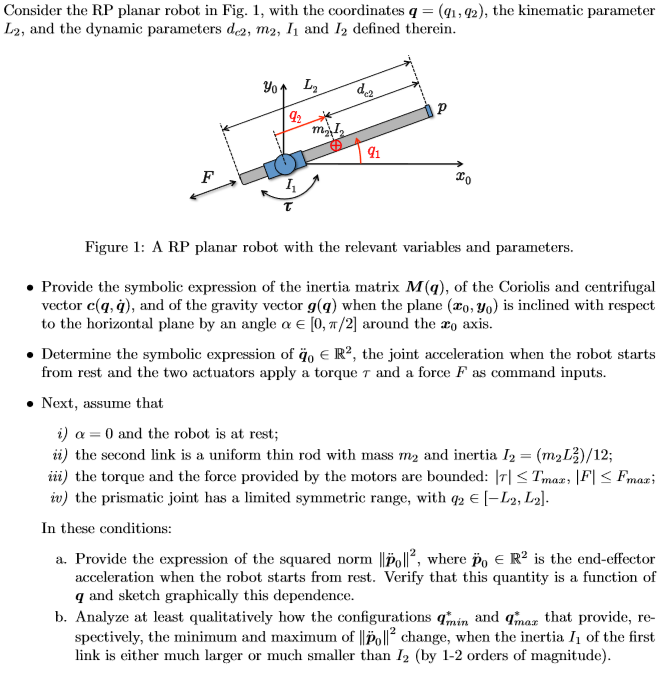

## my aproach

clear all, clc, close all
% This part is isolated from previous sectionclear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
% g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% g=[0,-g0*sin(alpha_angle),0]';
g=[0,-g0*sin(alpha_angle),-g0*cos(alpha_angle)]';
R2Robot=['rp';'xx';sigma]    

R2Robot = 3×2 char array
    'rp'
    'xx'
    ' '


z = Gen_param(n);

z = struct with fields:
        sigmaD: []
             l: []
            l_: []
             q: []
         q_dot: []
            q_: []
        q_dot_: []
            dc: []
             m: []
             I: {}
       methodD: 1
       dhTable: []
    firstParam: 'alpha'
             t: [1×1 sym]


z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%with DH table

z = struct with fields:
          sigmaD: [3×2 char]
               l: [2×1 sym]
              l_: []
               q: [2×1 sym]
           q_dot: [2×1 sym]
              q_: []
          q_dot_: []
              dc: [2×1 sym]
               m: [2×1 sym]
               I: [2×1 sym]
         methodD: 1
         dhTable: []
      firstParam: 'alpha'
               t: [1×1 sym]
              rc: []
    movingframes: []
               n: 2
          angle_: [1×2 sym]
       rcdefined: 1
        opt_expr: []
        collides: []
        joint_on: 1
          xyonly: 0


% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};!! pay attention to this
% z.rcdefined=true;

%% the following assumptions are due to the inexistence of l1 and dc1   
dc(1)=0

$$dc = \left(\begin{array}{c} 0\\ {\mathrm{dc}}_{2} \end{array}\right)$$

l(1)=0

$$l = \left(\begin{array}{c} 0\\ l_{2} \end{array}\right)$$

z.dc=dc;
z.l=l;
% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
[Pc,vc,w,T,Ti,M] = getGenericPC2(z);

rcdefined = logical
   1


z = struct with fields:
          sigmaD: [3×2 char]
               l: [2×1 sym]
              l_: []
               q: [2×1 sym]
           q_dot: [2×1 sym]
              q_: []
          q_dot_: []
              dc: [2×1 sym]
               m: [2×1 sym]
               I: [2×1 sym]
         methodD: 1
         dhTable: []
      firstParam: 'alpha'
               t: [1×1 sym]
              rc: []
    movingframes: []
               n: 2
          angle_: [1×2 sym]
       rcdefined: 1
        opt_expr: {[1×1 sym]  [1×1 sym]}
        collides: []
        joint_on: 1
          xyonly: 0


si falla aquí está el error


anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!


$$TTotal = \left(\begin{array}{cccc} \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & q_{2}\,\cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & q_{2}\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$RTotal = \left(\begin{array}{ccc} \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ 0 & -1 & 0 \end{array}\right)$$

$$PTotal = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$Pc = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$ThetaTotal = q_{1}$$

$$ThetaPartial = \left(\begin{array}{c} q_{1}\\ 0 \end{array}\right)$$

$$PTotali = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

n = 2

TPartial = 1×2 cell array
    {4×4 sym}    {4×4 sym}


RPartial = 1×2 cell array
    {3×3 sym}    {3×3 sym}


PPartial = 1×2 cell array
    {3×1 sym}    {3×1 sym}


RTotali = 1×2 cell array
    {3×3 sym}    {3×3 sym}


moving frames OFF!!
moving frames OFF!!


$$To\_derive = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


T

$$T = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

Ti

$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

M

$$M = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


cac

$$cac = \left(\begin{array}{c} q_{2}\,\left(2\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\right)\\ -q_{2}\,\left(m_{2}\,{{\dot{q}}_{1}}^{2}\right) \end{array}\right)$$

## gravity computation

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,m_{2}\,q_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)$$

$$PE\_short = g_{0}\,m_{2}\,q_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)$$

$$g\_q\_short = \left(\begin{array}{c} g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)\\ g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right) \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)\\ g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right) \end{array}\right)$$

$$PE = g_{0}\,m_{2}\,q_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)$$

U = 1×2 cell array
    {1×1 sym}    {1×1 sym}


$$g\_q\_short = \left(\begin{array}{c} g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)\\ g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right) \end{array}\right)$$

$$PE\_short = g_{0}\,m_{2}\,q_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)$$

U{:}

$$ans = 0$$

$$ans = g_{0}\,m_{2}\,q_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)$$

## symbolic expression for q_ddot in rest possition coriolis equal to cero

tau=sym('tau','real')

$$tau = \tau$$

u_ =[sym('tau','real'),sym('F','real')]'

$$u\_ = \left(\begin{array}{c} \tau \\ F \end{array}\right)$$

u =simplify( M*q_ddot + cac+g_q)

$$u = \left(\begin{array}{c} {\ddot{q}}_{1}\,\left(m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+2\,m_{2}\,q_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)\\ m_{2}\,\left(-q_{2}\,{{\dot{q}}_{1}}^{2}+{\ddot{q}}_{2}+g_{0}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)\right) \end{array}\right)$$

q_ddot_=inv(M)*(u_-(cac+g_q))

$$q\_ddot\_ = \left(\begin{array}{c} -\frac{2\,m_{2}\,q_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}-\tau +g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)}{m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}}\\ \frac{m_{2}\,q_{2}\,{{\dot{q}}_{1}}^{2}+F-g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)}{m_{2}} \end{array}\right)$$

q_dot_0_=[0,0]' 

q_dot_0_ =      0
     0


q_ddot_0=subs(q_ddot_,q_dot,q_dot_0_)

$$q\_ddot\_0 = \left(\begin{array}{c} \frac{\tau -g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)}{m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}}\\ \frac{F-g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)}{m_{2}} \end{array}\right)$$

## assumptions

alpha_angle_=0

alpha_angle_ = 0

I_=I;
L=sym('L_',[n,1],'real')

$$L = \left(\begin{array}{c} L_{1}\\ L_{2} \end{array}\right)$$

I_(2)=m(2)*L(2)^2/12

$$I\_ = \left(\begin{array}{c} I_{1}\\ \frac{{L_{2}}^{2}\,m_{2}}{12} \end{array}\right)$$

q_rigid_=q;
q_rigid_(2)=q(2)+dc(2)

$$q\_rigid\_ = \left(\begin{array}{c} q_{1}\\ {\mathrm{dc}}_{2}+q_{2} \end{array}\right)$$

var2replace=[alpha_angle;I;q;q_dot];
var2replace_=[alpha_angle_;I_;q_rigid_;q_dot_0_];


## end-effector

z.xyonly=false

z = struct with fields:
          sigmaD: [3×2 char]
               l: [2×1 sym]
              l_: []
               q: [2×1 sym]
           q_dot: [2×1 sym]
              q_: []
          q_dot_: []
              dc: [2×1 sym]
               m: [2×1 sym]
               I: [2×1 sym]
         methodD: 1
         dhTable: []
      firstParam: 'alpha'
               t: [1×1 sym]
              rc: []
    movingframes: []
               n: 2
          angle_: [1×2 sym]
       rcdefined: 1
        opt_expr: {[1×1 sym]  [1×1 sym]}
        collides: []
        joint_on: 1
          xyonly: 0


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
          sigmaD: [3×2 char]
               l: [2×1 sym]
              l_: []
               q: [2×1 sym]
           q_dot: [2×1 sym]
              q_: []
          q_dot_: []
              dc: [2×1 sym]
               m: [2×1 sym]
               I: [2×1 sym]
         methodD: 1
         dhTable: []
      firstParam: 'alpha'
               t: [1×1 sym]
              rc: []
    movingframes: []
               n: 2
          angle_: [1×2 sym]
       rcdefined: 1
        opt_expr: {[1×1 sym]  [1×1 sym]}
        collides: []
        joint_on: 1
          xyonly: 0


si falla aquí está el error


anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!


$$TTotal = \left(\begin{array}{cccc} \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & q_{2}\,\cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & q_{2}\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$RTotal = \left(\begin{array}{ccc} \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ 0 & -1 & 0 \end{array}\right)$$

$$PTotal = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$Pc = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$ThetaTotal = q_{1}$$

$$ThetaPartial = \left(\begin{array}{c} q_{1}\\ 0 \end{array}\right)$$

$$PTotali = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

n = 2

TPartial = 1×2 cell array
    {4×4 sym}    {4×4 sym}


RPartial = 1×2 cell array
    {3×3 sym}    {3×3 sym}


PPartial = 1×2 cell array
    {3×1 sym}    {3×1 sym}


RTotali = 1×2 cell array
    {3×3 sym}    {3×3 sym}


moving frames OFF!!
moving frames OFF!!


$$To\_derive = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{cc} 0 & \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\\ 0 & \sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$f = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right)\\ q_{1} \end{array}\right)$$

$$J = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 1 & 0 \end{array}\right)$$

$$V = \left(\begin{array}{c} {\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ {\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ {\dot{q}}_{1} \end{array}\right)$$

$$J\_ps = \left(\begin{array}{ccc} -\frac{q_{2}\,\sin\left(q_{1}\right)}{{q_{2}}^{2}+1} & \frac{q_{2}\,\cos\left(q_{1}\right)}{{q_{2}}^{2}+1} & \frac{1}{{q_{2}}^{2}+1}\\ \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [3×2 sym]
              Pc: [3×2 sym]
              vc: [3×2 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×2 sym]
               w: [3×2 sym]
               T: [1×1 sym]
              Ti: [1×2 sym]
               M: [2×2 sym]


PC_EEShort = struct with fields:
          f: [3×1 sym]
          J: [3×2 sym]
          V: [3×1 sym]
         Pc: [3×2 sym]
    Pc_ddot: []
    PTotali: [3×2 sym]


VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


PCVar.Pc

$$ans = \left(\begin{array}{cc} 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

PCVar.vc

$$ans = \left(\begin{array}{cc} 0 & {\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ 0 & {\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

PCVar.Pc_ddot

$$ans = \left(\begin{array}{cc} 0 & -q_{2}\,\cos\left(q_{1}\right)\,{{\dot{q}}_{1}}^{2}-2\,{\dot{q}}_{2}\,\sin\left(q_{1}\right)\,{\dot{q}}_{1}+{\ddot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\ddot{q}}_{1}\,\sin\left(q_{1}\right)\\ 0 & -q_{2}\,\sin\left(q_{1}\right)\,{{\dot{q}}_{1}}^{2}+2\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)\,{\dot{q}}_{1}+{\ddot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\ddot{q}}_{1}\,\cos\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

PCVar.M

$$ans = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

## subs

q_ddot_0_=q_ddot_0%subs(q_ddot_0,var2replace,var2replace_)

$$q\_ddot\_0\_ = \left(\begin{array}{c} \frac{\tau -g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)}{m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}}\\ \frac{F-g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)}{m_{2}} \end{array}\right)$$


var2replace2=[alpha_angle;I;q_dot;q_ddot];
var2replace2_=[alpha_angle_;I;q_dot_0_;q_ddot_0_];

q_ddot_0_=subs(q_ddot_0,var2replace2,var2replace2_)

$$q\_ddot\_0\_ = \left(\begin{array}{c} \frac{\tau }{m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}}\\ \frac{F}{m_{2}} \end{array}\right)$$


var2replace2=[alpha_angle;I;q_dot;q_ddot];% ya no meto q2 and dc
var2replace2_=[alpha_angle_;I;q_dot_0_;q_ddot_0_];

Pc_ddot_=subs(PCVar.Pc_ddot(:,2),var2replace,var2replace_)

$$Pc\_ddot\_ = \left(\begin{array}{c} {\ddot{q}}_{2}\,\cos\left(q_{1}\right)-{\ddot{q}}_{1}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}+q_{2}\right)\\ {\ddot{q}}_{2}\,\sin\left(q_{1}\right)+{\ddot{q}}_{1}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}+q_{2}\right)\\ 0 \end{array}\right)$$

Pc_ddot_arg_=simplify(Pc_ddot_'*Pc_ddot_)

$$Pc\_ddot\_arg\_ = {{\mathrm{dc}}_{2}}^{2}\,{{\ddot{q}}_{1}}^{2}+2\,{\mathrm{dc}}_{2}\,q_{2}\,{{\ddot{q}}_{1}}^{2}+{q_{2}}^{2}\,{{\ddot{q}}_{1}}^{2}+{{\ddot{q}}_{2}}^{2}$$



% Pc_ddot2_=simplify(subs(PCVar.Pc_ddot(:,2),var2replace2,var2replace2_))
% Pc_ddot2_arg_=simplify(expand(Pc_ddot2_'*Pc_ddot2_))

Pc_ddot2_=simplify((subs(Pc_ddot_arg_,var2replace2,var2replace2_)))

$$Pc\_ddot2\_ = \frac{F^{2}}{{m_{2}}^{2}}+\frac{{{\mathrm{dc}}_{2}}^{2}\,\tau^{2}}{{\left(m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)}^{2}}+\frac{{q_{2}}^{2}\,\tau^{2}}{{\left(m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)}^{2}}+\frac{2\,{\mathrm{dc}}_{2}\,q_{2}\,\tau^{2}}{{\left(m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)}^{2}}$$

## graphics

I_=I;
I_(2)=m(2)*L(2)^2/12

$$I\_ = \left(\begin{array}{c} I_{1}\\ \frac{{L_{2}}^{2}\,m_{2}}{12} \end{array}\right)$$

fac_I=sym('fac_I','real')

$$fac\_I = {\mathrm{fac}}_{I}$$

F=sym('F','real')

$$F = F$$

L_=[L(1),0.5]' 

$$L\_ = \left(\begin{array}{c} L_{1}\\ \frac{1}{2} \end{array}\right)$$

q_2_=-L_(2):0.001:L_(2);
dc_=[dc(1),0.25]' ;
F_=0;
tau_=1;
m_=[1,1]' ;
I_=subs(I_,[L(2),m(2)],[L_(2),m_(2)]);
I_=subs(I_,I(1),fac_I*I_(2))

$$I\_ = \left(\begin{array}{c} \frac{{\mathrm{fac}}_{I}}{48}\\ \frac{1}{48} \end{array}\right)$$

Pc_ddot3_=subs(Pc_ddot2_,[F;tau;m;dc;I],[F_;tau_;m_;dc_;I_])

$$Pc\_ddot3\_ = \frac{q_{2}}{2\,{\left({q_{2}}^{2}+\frac{{\mathrm{fac}}_{I}}{48}+\frac{1}{48}\right)}^{2}}+\frac{1}{16\,{\left({q_{2}}^{2}+\frac{{\mathrm{fac}}_{I}}{48}+\frac{1}{48}\right)}^{2}}+\frac{{q_{2}}^{2}}{{\left({q_{2}}^{2}+\frac{{\mathrm{fac}}_{I}}{48}+\frac{1}{48}\right)}^{2}}$$


Pc_ddot3_50=subs(Pc_ddot3_,fac_I,50);
Pc_ddot3_20=subs(Pc_ddot3_,fac_I,20);
Pc_ddot3_10=subs(Pc_ddot3_,fac_I,10);

Pc_ddot3_div_50=subs(Pc_ddot3_,fac_I,1/1);
Pc_ddot3_div_20=subs(Pc_ddot3_,fac_I,1/10);
Pc_ddot3_div_10=subs(Pc_ddot3_,fac_I,1/100);


## pltting

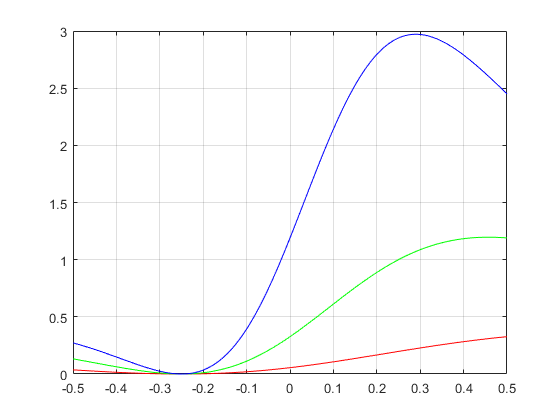


Pc_ddot3_50_=subs(Pc_ddot3_50,q(2),q_2_);
Pc_ddot3_20_=subs(Pc_ddot3_20,q(2),q_2_);
Pc_ddot3_10_=subs(Pc_ddot3_10,q(2),q_2_);
figure()
plot(q_2_,Pc_ddot3_50_,'red',q_2_,Pc_ddot3_20_,'green',q_2_,Pc_ddot3_10_,'blue')
grid on;

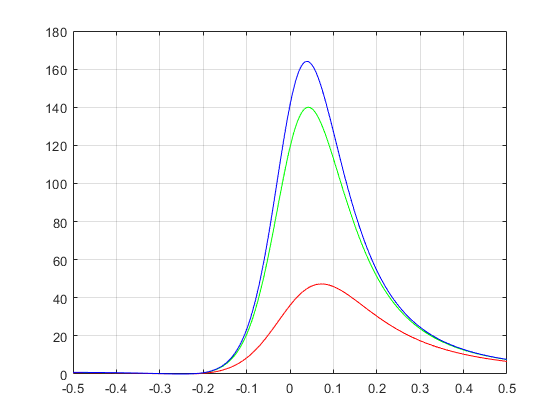


Pc_ddot3_div_50_=subs(Pc_ddot3_div_50,q(2),q_2_);
Pc_ddot3_div_20_=subs(Pc_ddot3_div_20,q(2),q_2_);
Pc_ddot3_div_10_=subs(Pc_ddot3_div_10,q(2),q_2_);
figure()
plot(q_2_,Pc_ddot3_div_50_,'red',q_2_,Pc_ddot3_div_20_,'green',q_2_,Pc_ddot3_div_10_,'blue')
grid on;


% Pc_ddot3_20_=subs(Pc_ddot3_,fac_I,20);
% Pc_ddot3_10_=subs(Pc_ddot3_,fac_I,10);
% 
% Pc_ddot3_div_50_=subs(Pc_ddot3_,fac_I,1/50);
% Pc_ddot3_div_20_=subs(Pc_ddot3_,fac_I,1/20);
% Pc_ddot3_div_10_=subs(Pc_ddot3_,fac_I,1/10);



% I_=[]

## arci approach

% 
% sigma = [0,1]
% n = length(sigma)
% I = sym('I', [n,1]);
% q = sym('q', [n,1]);
% m = sym('m', [n,1]);
% d = sym('d', [n,1]);
% qd = sym('qd', [n,1]);
% l = sym('l', [n,1]);
% qdd = sym('qdd', [n,1]);
% 
% syms g0 alpha tau F
% 
% g = [0 g0*sin(alpha) 0].' 
% 
% % adds -pi/2 to q(1) to fit the cartesian plane
% dhTable = [-pi/2 0 0 q(1)-pi/2;
%            0 0 q(2) 0]
%        

% [KE, T] = getKEwithJacobian(dhTable, sigma, q,qd,l,m, I,d,0)
% T{1}
% T{2}

% M = getInertiaMatrixFromKE(KE,qd)
% [c,S] = getcS(M,q,qd)

% [g_q , PE, U] = getGravityWithJacobian(dhTable,q,l, m, d, g)

### Robot at rest 

% subs(M*qdd + c + g_q,qd,zeros(length(qd),1))

% 
% 
% qdd0 = solve(subs(M*qdd + c + g_q,qd,zeros(length(qd),1)) == [tau,F].', qdd)

% qdd0.qdd1
% qdd0.qdd2

### Expression for acceleration norm

% dhTableEE = dhTable
% dhTableEE(2,3) = q(2)+d(2) % add this distance for endEffector
% 
% [TTotal,TPartial]=getTransformationMatrix(dhTableEE,'alpha')
% 
% %Position of the end effector
% p_EE = simplify(TTotal(1:2,4))

% syms q1(t) q2(t) t
% p_EE = subs(p_EE,q,[q1,q2].')

% v_EE = diff(p_EE,t)
% a_EE = diff(v_EE,t)

% a_EE0= subs(a_EE, diff([q1,q2],t),[0,0])

% norm0 = simplify(a_EE0.'*a_EE0)


## Exercise 2